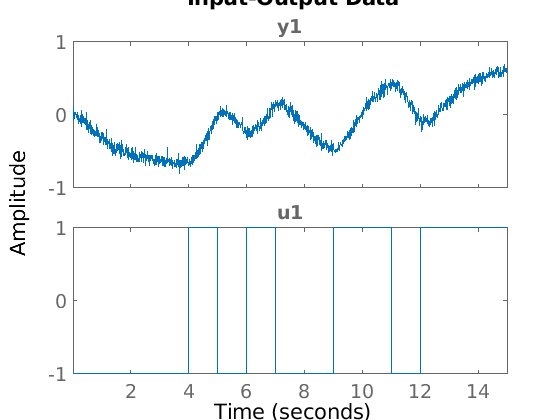

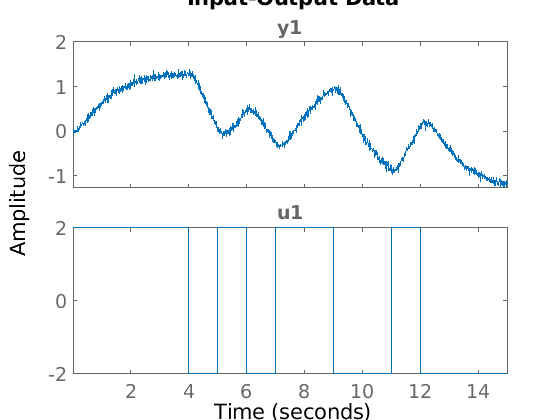

clear;
stepStruct = load("Simulated_stepdata.mat");
trainingStruct = load("Simulated_data1.mat");
validationStruct = load("Simulated_data2.mat");

Ts = trainingStruct.Ts;
dataStep = iddata(stepStruct.y, stepStruct.u, Ts, 'InterSample', 'zoh');
dataEst= iddata(trainingStruct.y, trainingStruct.u, Ts, 'Intersample', 'zoh');
dataVal = iddata(validationStruct.y, validationStruct.u, Ts, 'Intersample', 'zoh');
idplot(dataEst);
idplot(dataVal);

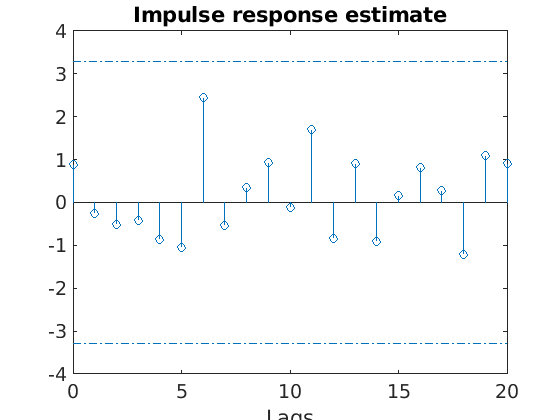

% estimate impulse response from time domain data:
% not really helpful for us
ir = cra(dataEst);

% delay in sampling times
nk = delayest(dataEst)

nk = 28

% prepare srivcstruc
% parameter numbers numerator
nb_min = 1; nb_max = 3;
% parameter numbers denominator
nf_min = 1; nf_max = 3;
% range of delay in sampling times
nk_min = nk - 1; nk_max = nk + 1;

nn = [nb_min nf_min nk_min;
        nb_max nf_max nk_max];
% we supply dataValid, cross validation is integrated
V = srivcstruc(dataEst, dataVal, nn);


Elapsed time :  0 h  0 min 22 s 



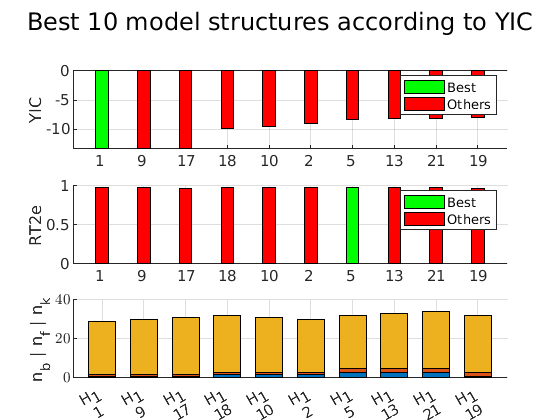

% display ten best model structures
selcstruc(V,'srivc','Nmodels',10);

% model number 1 is the best: first order plus delay
% second and third best just have a different delay
best_nb = 1;
best_nf = 1;

% refined search for best delay
nn_refined = [1 1 nk - 10;
        1 1 nk + 10];
V_refined = srivcstruc(dataEst, dataVal, nn_refined);


Elapsed time :  0 h  0 min  6 s 



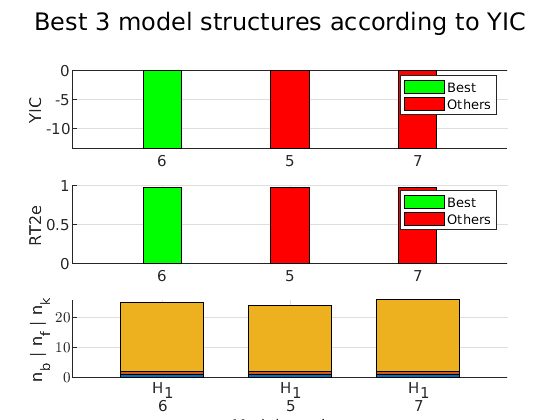

selcstruc(V_refined, 'srivc', 'Nmodels', 3);

% in the refined search, model nr 6 is the best
% do V(1:end, 1:3) to see mapping model nr -> (nb, nf, nk)
best_nk = V_refined(6, 3);
% 23

M = srivc(dataEst, [best_nb best_nf best_nk]);
present(M);

                                                                                                                     
M =                                                                                                                  
Continuous-time OE model: y(t) = [B(s)/F(s)]u(t)                                                                     
  B(s) = 0.5526 (+/- 0.003706)                                                                                       
                                                                                                                     
  F(s) = s + 0.8093 (+/- 0.007223)                                                                                   
                                                                                                                     
Input delays (listed by channel): 0.23                                                                               
Parameterization:                                       

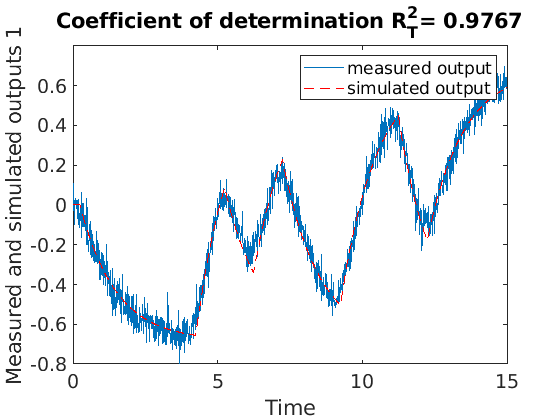

% see fit on estimation and on validation data
figure;
comparec(dataEst,M);

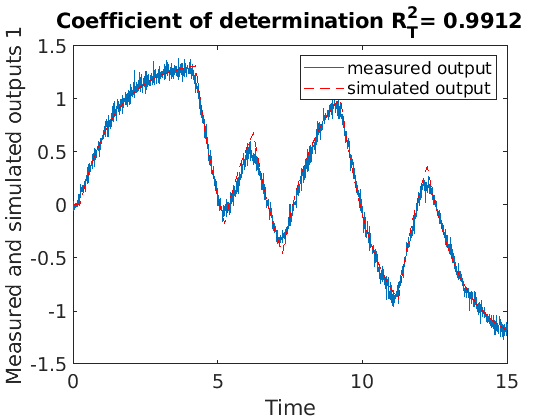

comparec(dataVal, M);

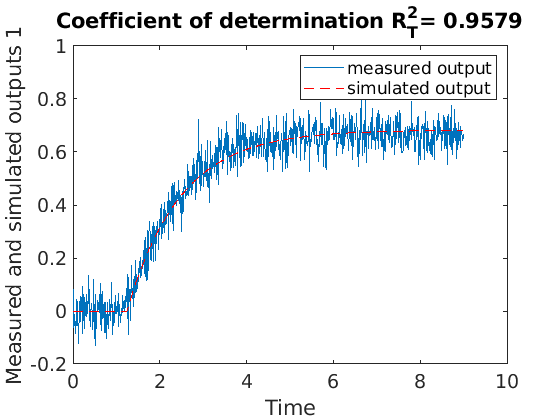

comparec(dataStep, M);

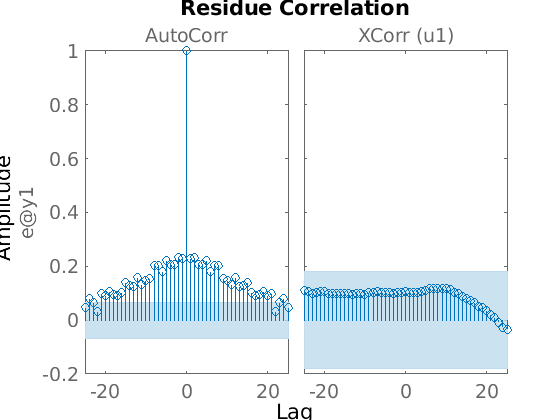

% residual analysis
resid(dataEst, M);

Tests of other methods to estimate transfer function with knowledge about suited structure. All show similar results.

% test other methods
% attention: tfest takes #zeros as param, NOT #params in numerator
M_tfest = tfest(dataEst, 1, 0, NaN)

M_tfest =
 
  From input "u1" to output "y1":
                   0.5714
  exp(-0.28*s) * ----------
                 s + 0.8569
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                             
Estimated using TFEST on time domain data "dataEst".
Fit to estimation data: 84.08%                      
FPE: 0.003304, MSE: 0.003291                        


% coefficient of determination NOT significantly better in each case
% comparec(dataEst,M_tfest);
% comparec(dataVal, M_tfest);
% comparec(dataStep, M_tfest);
% residual analysis shows higher cross correlation
% resid(dataEst, M_tfest);
% analysis of singular values also speaks for first order!
% Gss = ssest(dataEst, 1:3);

TFest with merging step and data1: no significant improvement

dataEstBig = merge(dataEst, dataStep);
M_tfest_new = tfest(dataEstBig, 1, 0, NaN)

M_tfest_new =
 
  From input "u1" to output "y1":
                   0.5784
  exp(-0.28*s) * ----------
                 s + 0.8596
 
Continuous-time identified transfer function.

Parameterization:
   Number of poles: 1   Number of zeros: 0
   Number of free coefficients: 2
   Use "tfdata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                
Estimated using TFEST on time domain data "dataEstBig".
Fit to estimation data: [84.05 79.47]%                 
FPE: 0.003052, MSE: [0.003304 0.002606]                


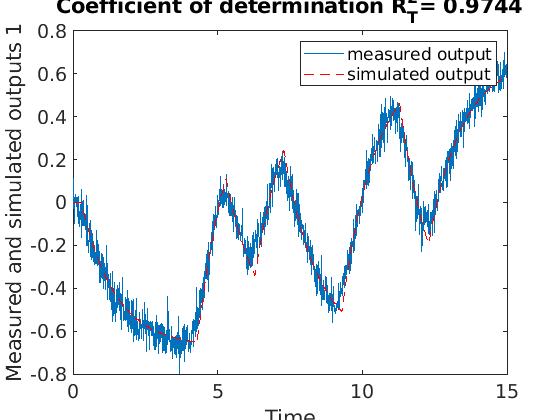

comparec(dataEst,M_tfest_new);

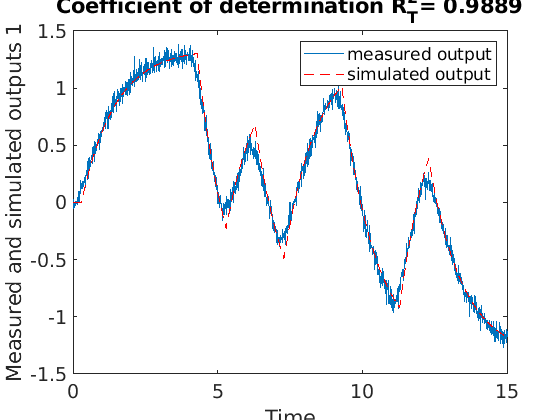

comparec(dataVal, M_tfest_new);

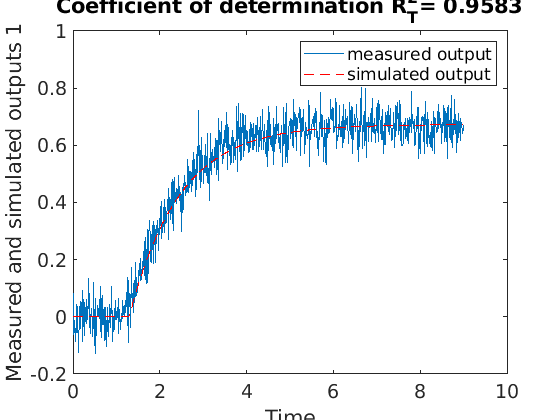

comparec(dataStep, M_tfest_new);

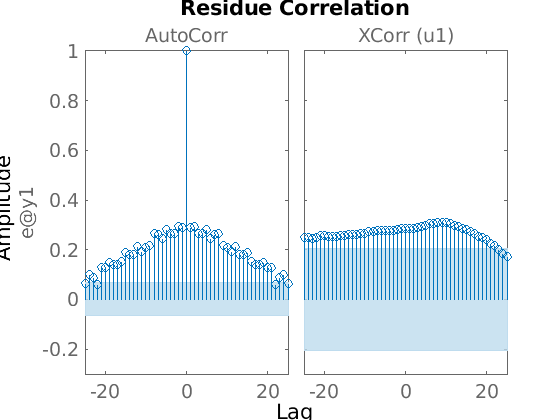

% residual analysis shows higher cross correlation
resid(dataEst, M_tfest_new);

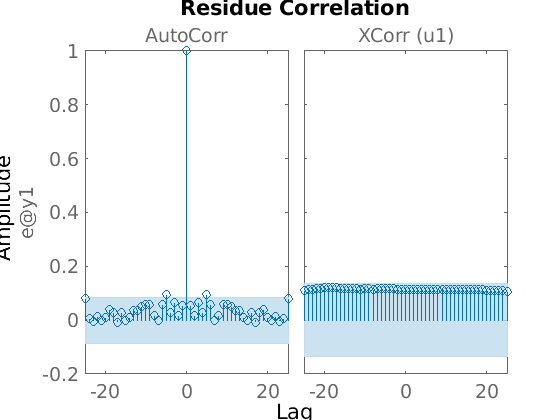

resid(dataStep, M_tfest_new);